# **Assignment 2**

## **Name: Muhammad Asad Imran Rafique**

## **Student ID: 48065145**

### 1a.

P_s = 2;
%% power = (A^2/2)
A = sqrt(P_s*2)

A = 2


SNRdB = [0, 3, 6, 10, 20, 30, 40, 50];
SNR = 10.^(SNRdB/10);
P_eta = P_s./SNR

P_eta =     2.0000    1.0024    0.5024    0.2000    0.0200    0.0020    0.0002    0.0000


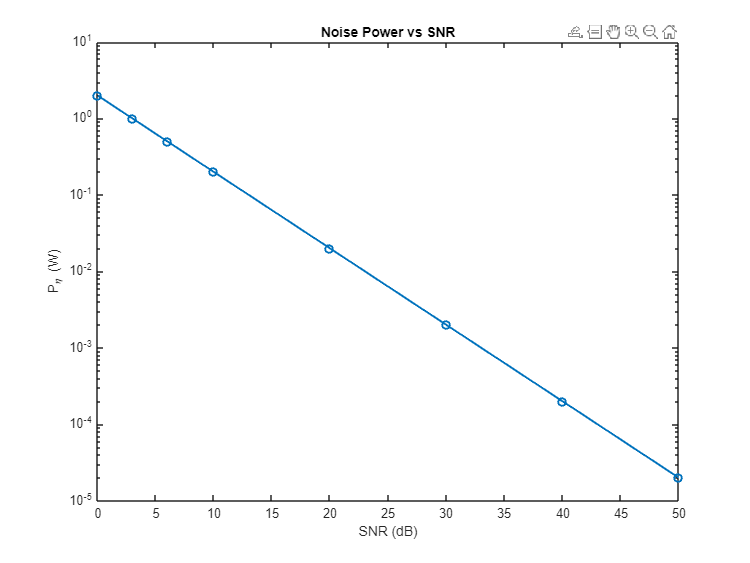


figure('Position', [100, 100, 800, 600]);
semilogy(SNRdB,P_eta, 'o-', 'LineWidth', 1.5);
xlabel("SNR (dB)");
ylabel("P_{\eta} (W)");
title("Noise Power vs SNR");

### 1b.

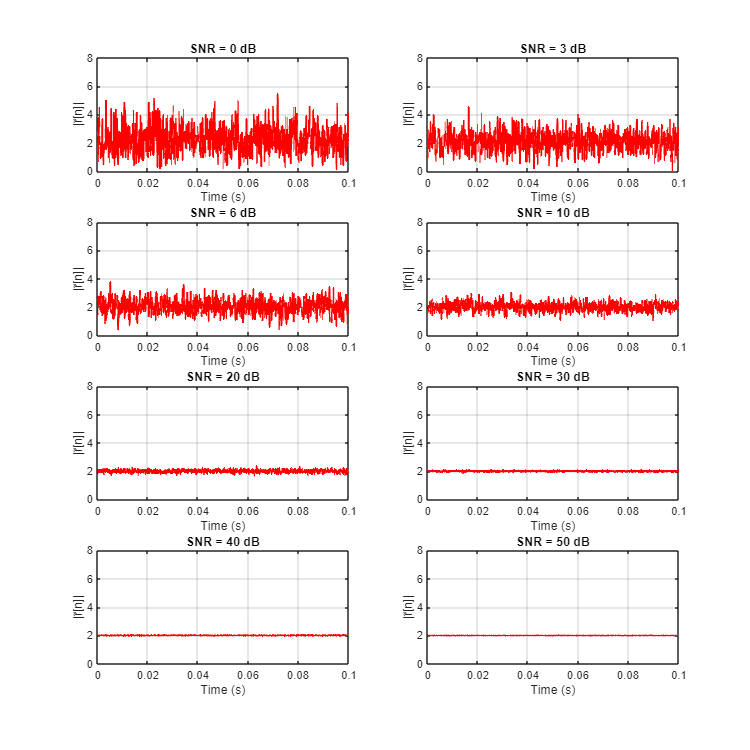

f1 = 2e3;
theta = 0;
fc = 1e3;
fs = 10e3;
Ts = 1/fs;
n = 1:1000;
t = (n-1)*Ts;

s_t = A * cos(2 * pi * f1 * t + theta);
s_tilde = A.*exp(-1j * 2 * pi * (f1-fc) * t);


figure('Position', [100, 100, 800, 800]);
for i = 1:length(SNRdB)
    sigma = sqrt(P_eta(i));    
    eta_tilde = sigma / sqrt(2) * (randn(size(t)) + 1j * randn(size(t)));    
    r_tilde = s_tilde + eta_tilde;    
    r_tilde_abs = abs(r_tilde);    
    % Plot |r_tilde| vs time
    subplot(4, 2, i);
    plot(t, r_tilde_abs, 'r', 'LineWidth', 1.5);
    xlabel('Time (s)');
    ylabel('|r̃[n]|');
    title(['SNR = ', num2str(SNRdB(i)), ' dB']);
    xlim([0, 0.1]);
    ylim([0, 8]);
    grid on;
end

### 2a.

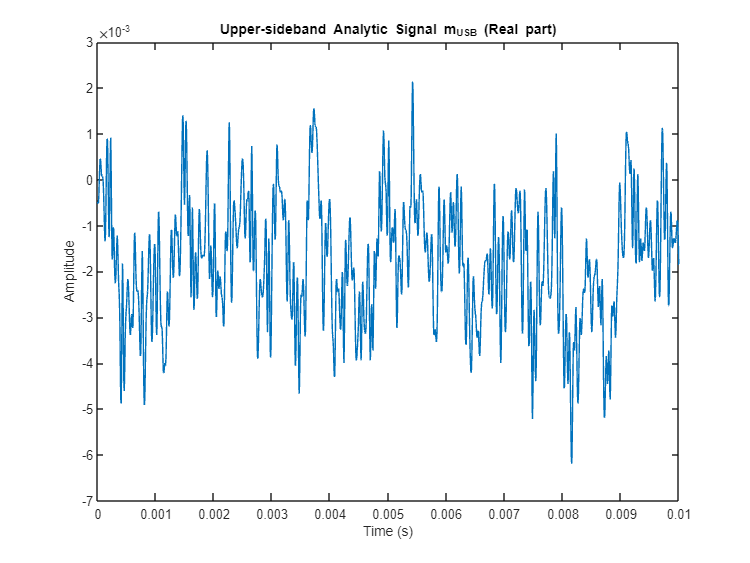

[y, fs] = audioread('speech.wav');
N = length(y);
n = 0:N-1;
t = n / fs;
%frequencies = fs/N * (-(N-1)/2:(N-1)/2);
y_analytic = hilbert(y);
%Fourier Transform of message
Y_analytic = fft(y_analytic);
%removing negative frequencies
Y_analytic(N/2:end) = 0;
%time domain upper sideband of message signal
m_usb = ifft(Y_analytic);
figure('Position', [100, 100, 800, 600]);
plot(t, real(m_usb));
xlabel('Time (s)');
ylabel('Amplitude');
title('Upper-sideband Analytic Signal m_{USB} (Real part)');
xlim([0 0.01]);

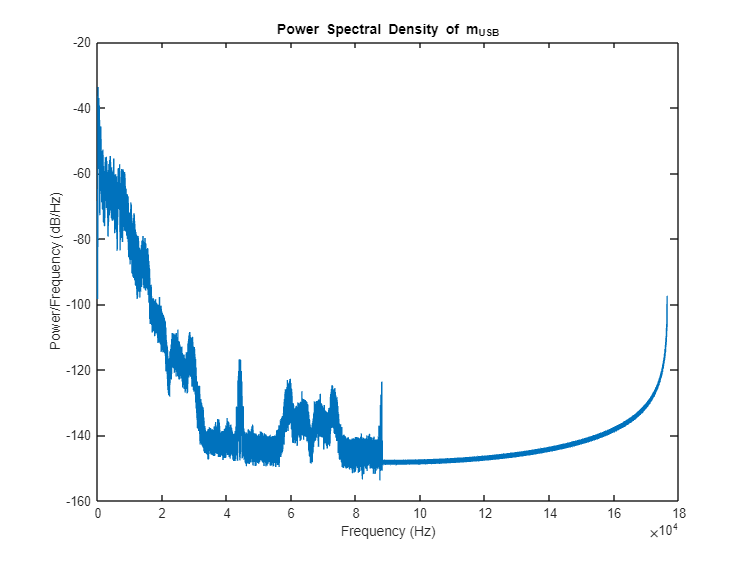


figure('Position', [100, 100, 800, 600]);
[Mxx, f1] = pwelch(m_usb, [], [], [], fs);
plot(f1, 10*log10((Mxx)));
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
title('Power Spectral Density of m_{USB}');

%xlim([0 fs/2]);

### 2b.

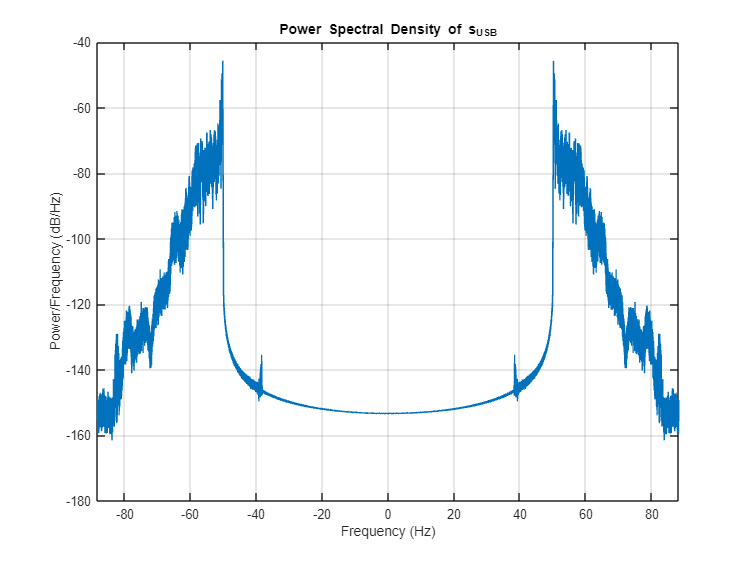

fc = 50e3;
s_usb = (0.5 * real(m_usb .* exp(1j*2*pi*fc*t')))';

figure('Position', [100, 100, 800, 600]);
pwelch(s_usb, [], [], [], fs, "centered");
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
title('Power Spectral Density of s_{USB}');

### 2c.

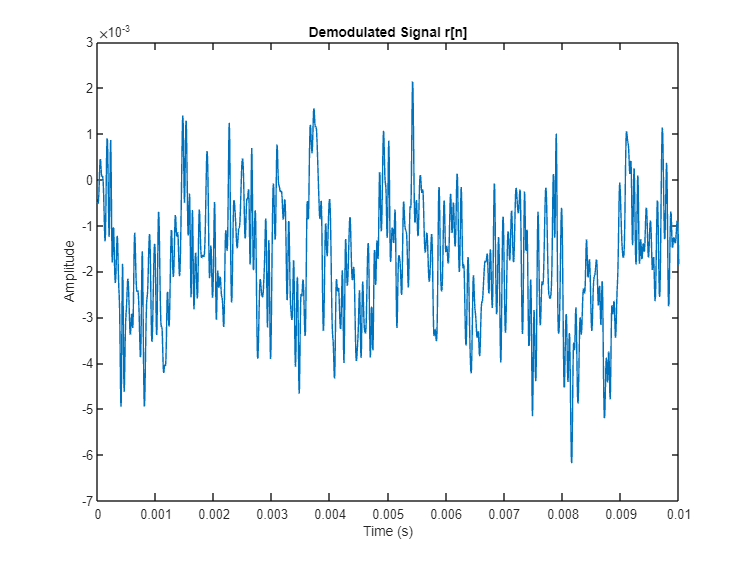

% getting analytic signal from s_usb
s_usb_analytic = hilbert(s_usb);
%demodulating using carrier frequency
r_n = 2*real(s_usb_analytic.* exp(-1j*2*pi*fc*t));

figure('Position', [100, 100, 800, 600]);
plot(t,r_n);
xlabel('Time (s)');
ylabel('Amplitude');
title('Demodulated Signal r[n]');
xlim([0 0.01]);

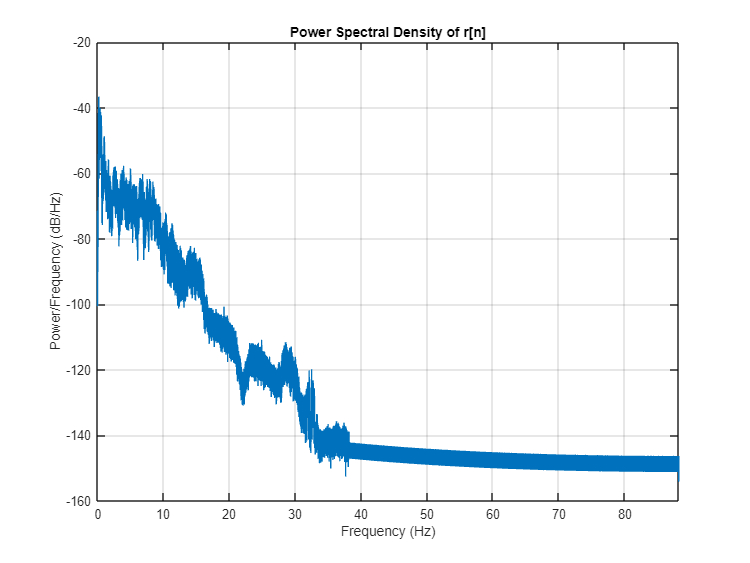


figure('Position', [100, 100, 800, 600]);
pwelch(r_n, [], [], [], fs);
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
title('Power Spectral Density of r[n]');

### 2d.

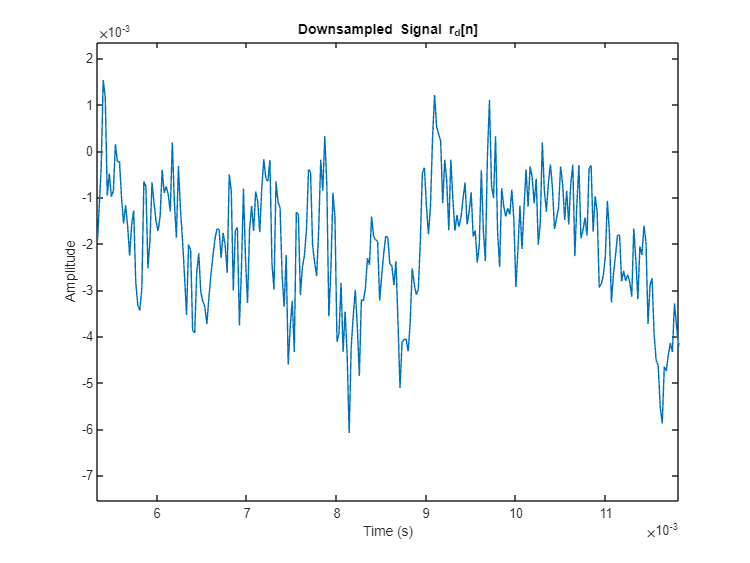

r_d = decimate(r_n,4);
fs_d = fs/4;
N_d = length(r_d);
n_d = (0:N_d-1);
t_d = n_d / fs_d;


figure('Position', [100, 100, 800, 600]);
plot(t_d, r_d);
xlabel('Time (s)');
ylabel('Amplitude');
title('Downsampled Signal r_d[n]');
xlim([0 0.01]);

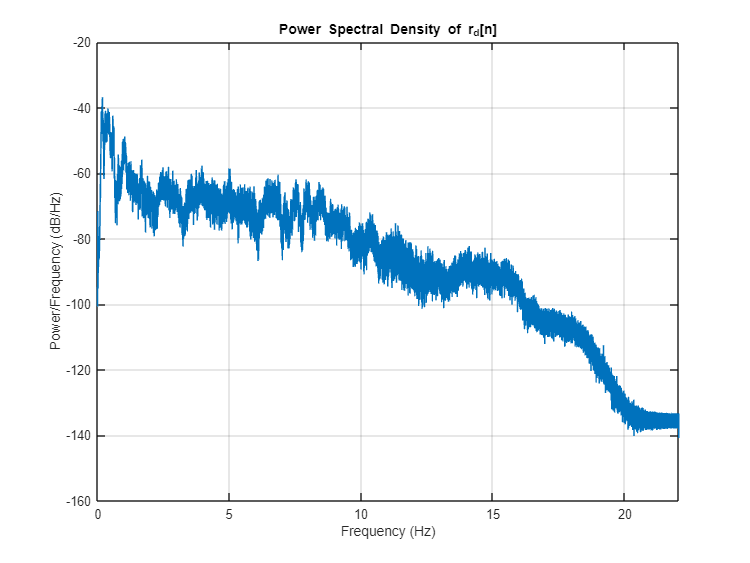


figure('Position', [100, 100, 800, 600]);
pwelch(r_d, [], [], [], fs_d);
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
title('Power Spectral Density of r_d[n]');

sound(y,fs)
 

sound(r_d,fs_d)
 

### 3a.

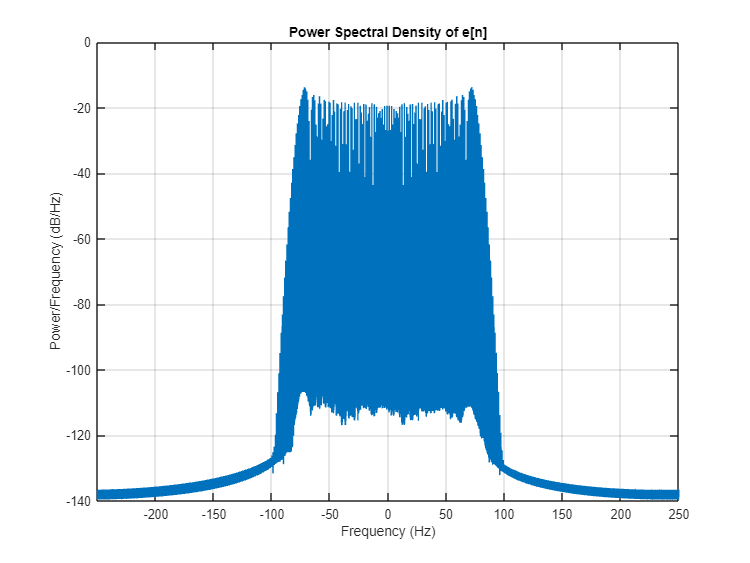

A = 1;
f_delta = 75e3;
fs = 500e3;
N = 5e6;
fm = 1e3;
n = 0:N-1;
t = n/fs;
m_n = cos(2*pi*fm/fs*n);
e_n = A * exp(1j * 2 * pi * f_delta * cumsum(m_n)/fs);
%e_n2 = A * exp(1j*2*pi*f_delta*sin(2*pi*fm*t)/(2*pi*fm));

figure('Position', [100, 100, 800, 600]);
pwelch(e_n, [], [], [], fs, "centered");
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
title('Power Spectral Density of e[n]');


    % figure;
    % plot(t(1:500), real(e_n(1:500)), 'b', 'LineWidth', 1.5);
    % hold on;
    % plot(t(1:500), imag(e_n(1:500)), 'r', 'LineWidth', 1.5);
    % hold off;
    % mod = fmmod(m_n,0,fs,f_delta,0);
    % demod = fmdemod(mod,fs/2,fs,f_delta,0);
    % figure;
    % plot(t(1:500), demod(1:500), 'b', 'LineWidth', 1.5); % Original message signal

### 3b.

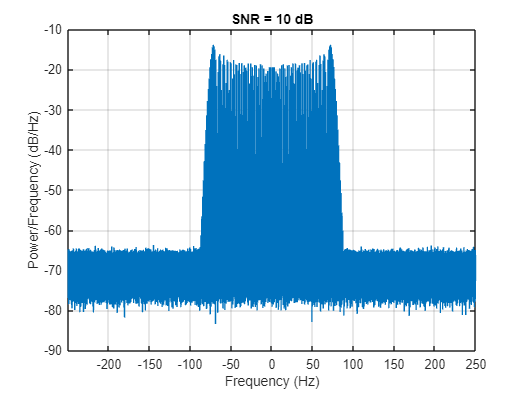

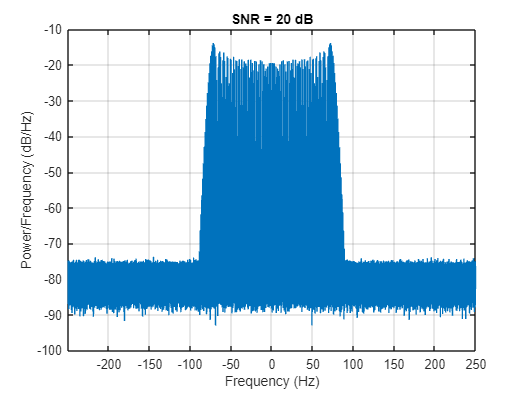

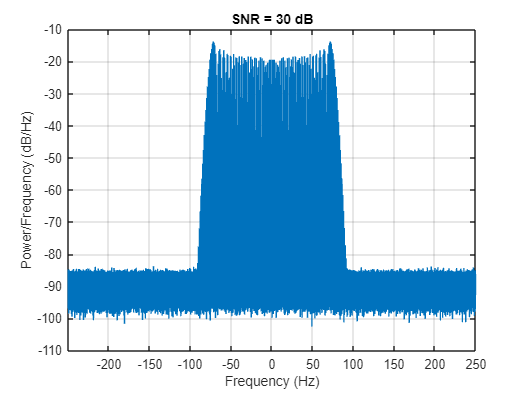

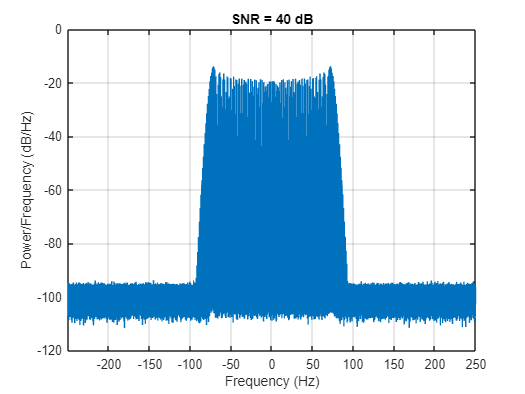

SNRdB = [10, 20, 30, 40];
SNR = 10.^(SNRdB/10);
P_e = A^2/2;
P_eta = P_e./SNR;
alpha_r = randn(size(n));
alpha_i = randn(size(n));
sigma = 1;
eta_n = sigma / sqrt(2) * (alpha_r + 1i * alpha_i);

r_n_SNR = cell(1, numel(SNRdB));

for i = 1:length(SNRdB)
    r_n_SNR{i} = e_n + sqrt(P_eta(i))*eta_n;
    figure;
    pwelch(r_n_SNR{i}, [], [], [], fs, "centered");    
    xlabel('Frequency (Hz)');
    ylabel('Power/Frequency (dB/Hz)');
    title(['SNR = ', num2str(SNRdB(i)), ' dB']);
    grid on;
end

### 3c.

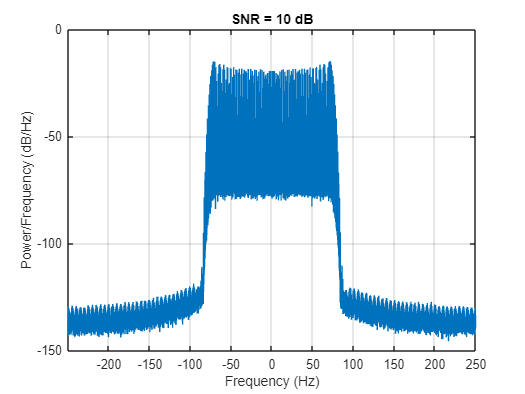

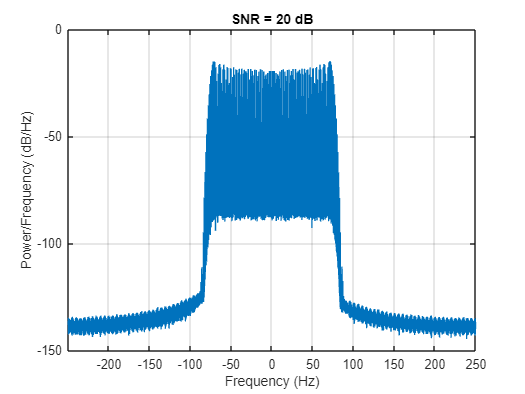

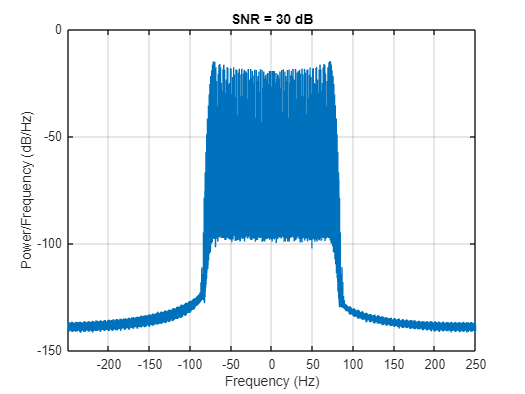

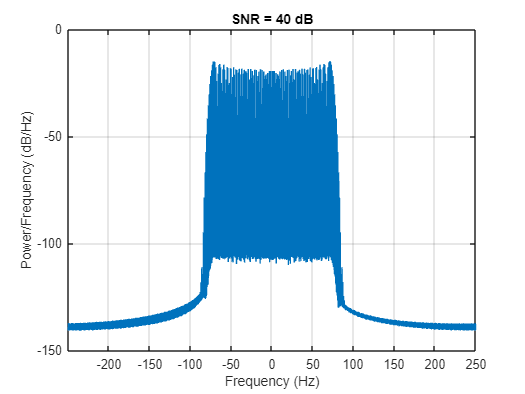

BW = f_delta + fm;
fc = BW / (fs/2);
b = fir1(100, fc);

r_lp_SNR = cell(1, numel(SNRdB));


for i = 1:length(r_n_SNR)
    r_lp_SNR{i} = filter(b, 1, r_n_SNR{i});
    figure;
    pwelch(r_lp_SNR{i}, [], [], [], fs, "centered");
    xlabel('Frequency (Hz)');
    ylabel('Power/Frequency (dB/Hz)');
    title(['SNR = ', num2str(SNRdB(i)), ' dB']);
    grid on;
end

### 3d.

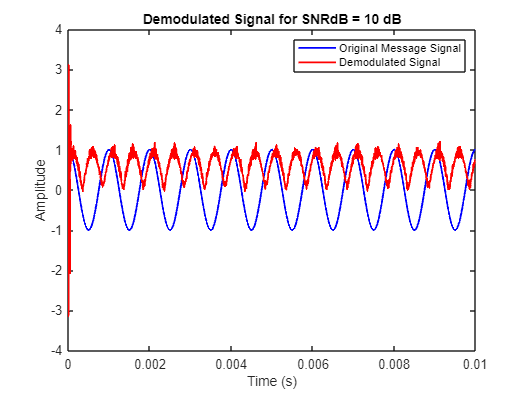

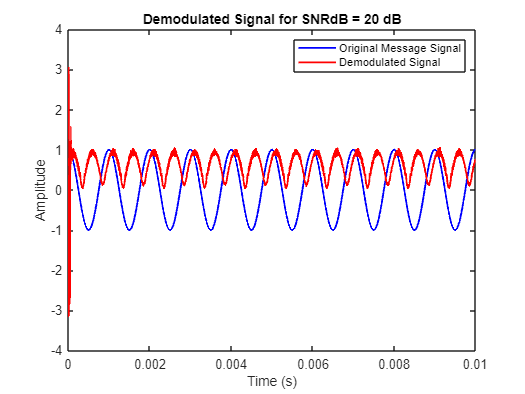

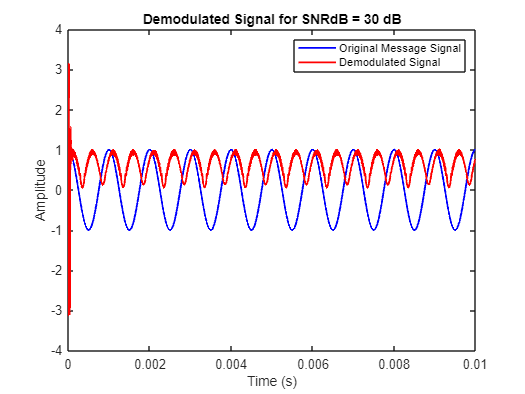

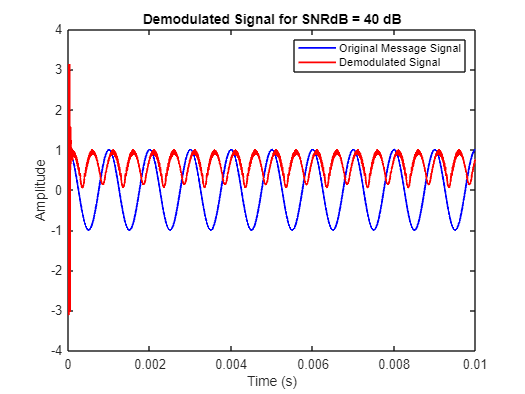

m_hat = cell(1, numel(SNRdB));
for i = 1:numel(SNRdB)

    analytic_r_n = hilbert(real(r_lp_SNR{i}));
    m_hat{i} = diff(unwrap(angle(analytic_r_n)));
    figure;
    plot(t(2:5000), m_n(2:5000), 'b', 'LineWidth', 1.5);
    hold on;
    plot(t(2:5000), m_hat{i}(2:5000), 'r', 'LineWidth', 1.5);
    hold off;
    title(['Demodulated Signal for SNRdB = ', num2str(SNRdB(i)), ' dB']);
    xlabel('Time (s)');
    ylabel('Amplitude');
    legend('Original Message Signal', 'Demodulated Signal');

end